datapath = fullfile(matlabroot, 'toolbox/nnet/nndemos/nndatasets/DigitDataset/');
dstore = imageDatastore(datapath, "IncludeSubfolders",true, "LabelSource","foldernames");
figure;
perm = randperm(10000, 20);
for i=1:20
    subplot(4,5,i);
    imshow(dstore.Files{perm(i)});
end

numLabels = countEachLabel(dstore)

numLabels = 10×2 table
    Label    Count
    _____    _____

      0      1000 
      1      1000 
      2      1000 
      3      1000 
      4      1000 
      5      1000 
      6      1000 
      7      1000 
      8      1000 
      9      1000 


[trainSet, testSet] = splitEachLabel(dstore, 750, 'randomized');

layers = [
    imageInputLayer([28 28 1])

    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2,'Stride', 2)

    convolution2dLayer(3,16, 'Padding','same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2,'Stride',2)

    convolution2dLayer(3,32, 'Padding','same')
    batchNormalizationLayer
    reluLayer

    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer
]

layers =   15×1 Layer array with layers:

     1   ''   Image Input             28×28×1 images with 'zerocenter' normalization
     2   ''   2-D Convolution         8 3×3 convolutions with stride [1  1] and padding 'same'
     3   ''   Batch Normalization     Batch normalization
     4   ''   ReLU                    ReLU
     5   ''   2-D Max Pooling         2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     6   ''   2-D Convolution         16 3×3 convolutions with stride [1  1] and padding 'same'
     7   ''   Batch Normalization     Batch normalization
     8   ''   ReLU                    ReLU
     9   ''   2-D Max Pooling         2×2 max pooling with stride [2  2] and padding [0  0  0  0]
    10   ''   2-D Convolution         32 3×3 convolutions with stride [1  1] and padding 'same'
    11   ''   Batch Normalization     Batch normalization
    12   ''   ReLU                    ReLU
    13   '

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |       16.41% |       14.64% |       2.7065 |       2.4183 |          0.0100 |
|       1 |          30 |       00:00:09 |       69.53% |       76.00% |       0.8810 |       0.7976 |          0.0100 |
|       1 |          50 |       00:00:11 |       89.84% |              |       0.5105 |              |          0.0100 |
|       2 |          60 |       00:00:12 |       88.28% |       88.68% |       0.4085 |   

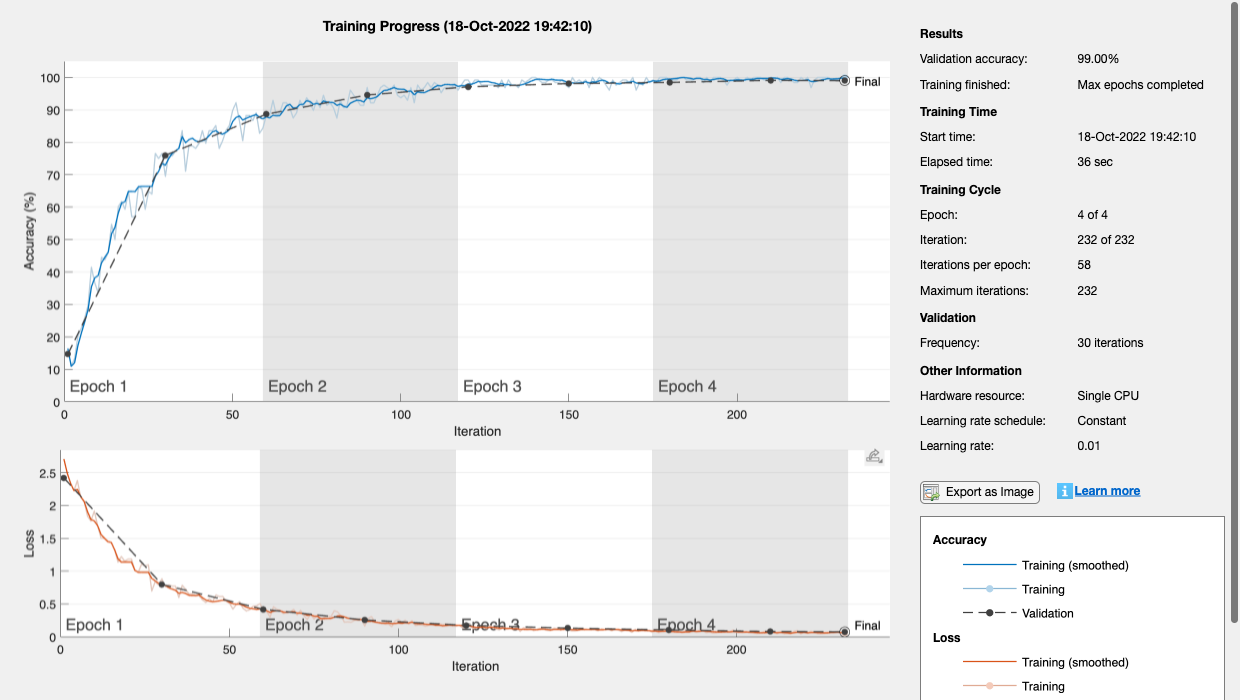

model =   SeriesNetwork with properties:

         Layers: [15×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


options = trainingOptions("sgdm", ...
    "InitialLearnRate", 0.01, ...
    "MaxEpochs",4, ...
    "Shuffle","every-epoch", ...
    "ValidationData",testSet, ...
    "ValidationFrequency",30, ...
    "Plots","training-progress");
model = trainNetwork(trainSet, layers, options)

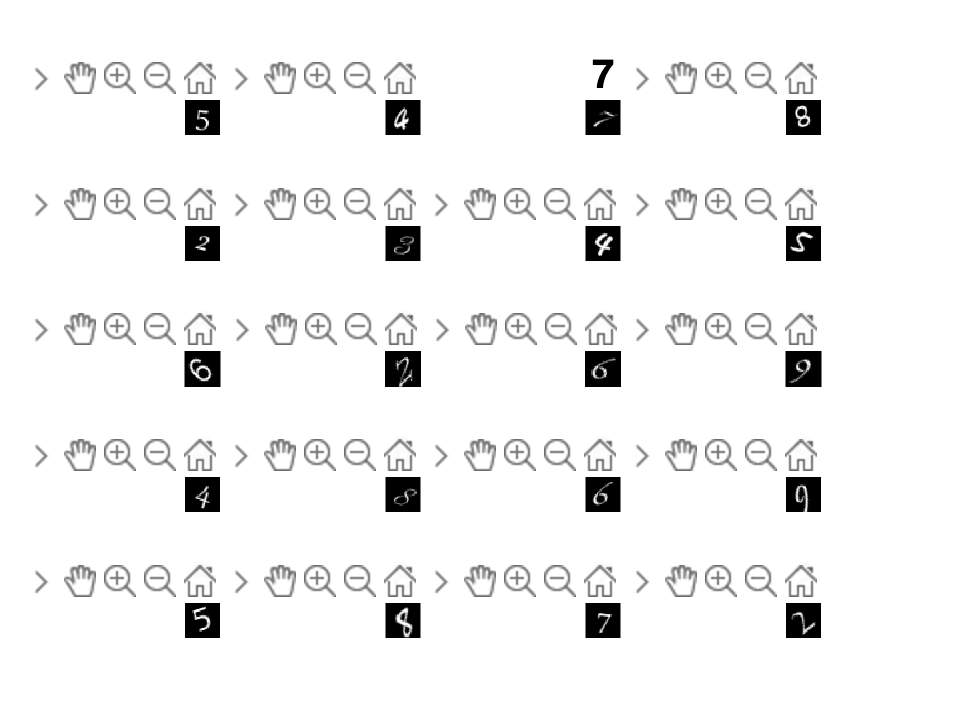

pred = classify(model, testSet);
figure;
randices = randperm(2500, 20);
for i=1:20
    subplot(5,4,i);
    imshow(testSet.Files{randices(i)});
    title(pred(randices(i)), 'FontSize', 20);
end